%% OSM STEP 2 - Check and convert selected OSM scenario

clear;
close all;
clc;

%% Select OSM scenario

% Available options:
% "openArea"                 -> previous campus/open-area scenario
% "piotrkowskaStreetCanyon"  -> new Piotrkowska street canyon scenario
%CHANGE
scenarioName = "piotrkowskaStreetCanyon";
  %scenarioName = "openArea";

%% Select files depending on scenario

switch scenarioName

    case "openArea"
        geojsonFile = "osm_buildings_raw.geojson";
        matOutputFile = "osm_buildings_local.mat";
        plotTitle = "Imported OSM building footprints - Open Area Scenario";

    case "piotrkowskaStreetCanyon"
        geojsonFile = "piotrkowska_buildings_raw.geojson";
        matOutputFile = "piotrkowska_buildings_local.mat";
        plotTitle = "Imported OSM building footprints - Piotrkowska Street Canyon";

    otherwise
        error("Unknown scenarioName: %s", scenarioName);

end

fprintf("Selected scenario: %s\n", scenarioName);

Selected scenario: piotrkowskaStreetCanyon


fprintf("GeoJSON file: %s\n", geojsonFile);

GeoJSON file: piotrkowska_buildings_raw.geojson


fprintf("MAT output file: %s\n\n", matOutputFile);

MAT output file: piotrkowska_buildings_local.mat




%% Check GeoJSON file

if ~isfile(geojsonFile)
    error("GeoJSON file not found: %s. Check that it is in the current MATLAB folder.", geojsonFile);
end

%% Read GeoJSON file

buildingsGT = readgeotable(geojsonFile);

fprintf("Number of imported building objects: %d\n", height(buildingsGT));

Number of imported building objects: 22


fprintf("Shape class: %s\n", class(buildingsGT.Shape));

Shape class: geopolyshape



disp("Available table variables:");

Available table variables:


disp(buildingsGT.Properties.VariableNames.');

    {'Shape'            }
    {'full_id'          }
    {'osm_id'           }
    {'osm_type'         }
    {'building'         }
    {'office'           }
    {'name:uk'          }
    {'name:ru'          }
    {'government'       }
    {'admin_level'      }
    {'addr:postcode'    }
    {'official_name'    }
    {'building:material'}
    {'amenity'          }
    {'comment'          }
    {'wikipedia'        }
    {'wikidata'         }
    {'tourism'          }
    {'source:addr'      }
    {'name'             }
    {'building:levels'  }
    {'addr:street'      }
    {'addr:housenumber' }
    {'addr:housename'   }
    {'addr:city'        }



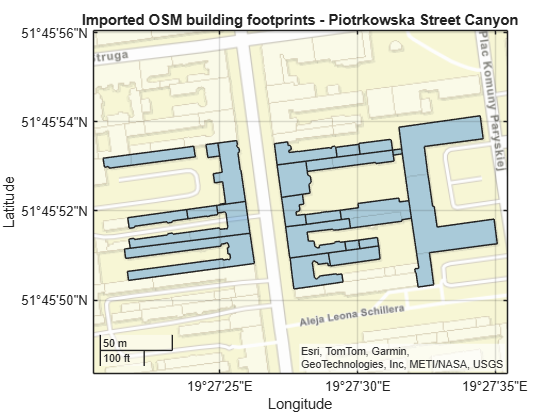

%% Plot buildings in geographic coordinates

figure;
geoplot(buildingsGT.Shape);
geobasemap streets;
title(plotTitle);

Number of imported building objects using readgeotable: 22
Shape class: geopolyshape
Number of GeoJSON features: 22

Local origin:
lat0 = 51.76446253 deg
lon0 = 19.45766262 deg

=== OSM Building Local XY Conversion Summary ===
Number of buildings: 22
x range: [-130.34, 143.02] m
y range: [-55.96, 63.95] m
Approx. local map width: 273.36 m
Approx. local map height: 119.90 m


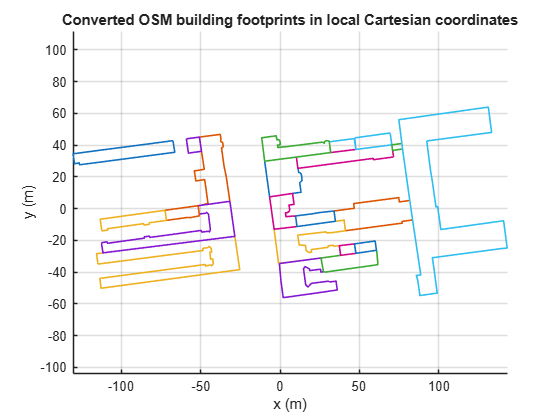


Saved local building structure to: piotrkowska_buildings_local.mat



%% OSM STEP 3 - Convert buildings to local x-y coordinates

clear helperConvertOSMBuildingsToLocalXY

osmLocal = helperConvertOSMBuildingsToLocalXY(geojsonFile, matOutputFile);

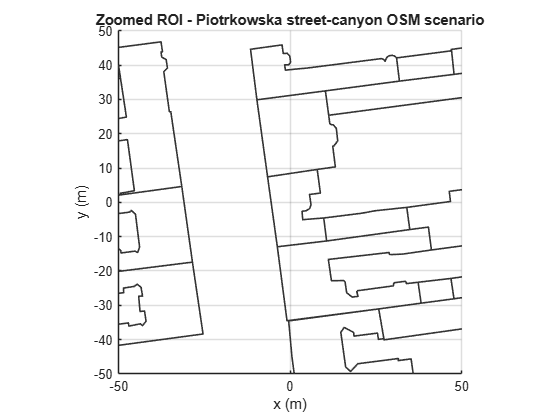

%% OSM STEP 4 - Select ROI and zoom into scenario

switch scenarioName

    case "openArea"

        % 100 m x 100 m ROI
        % Format: [xMin xMax; yMin yMax]
        scenarioROI = [-120  -20;
            -70   30];

        scenarioDescription = "Open-area OSM scenario";

    case "piotrkowskaStreetCanyon"

        % 100 m x 100 m ROI
        % Format: [xMin xMax; yMin yMax]
        scenarioROI = [-50   50;
            -50   50];

        scenarioDescription = "Piotrkowska street-canyon OSM scenario";

    otherwise
        error("Unknown scenarioName: %s", scenarioName);

end

%% Plot only building contours and zoom into ROI

figure("Name", "OSM scenario ROI zoom");
hold on;
grid on;
axis equal;

% Plot all building contours
for iB = 1:numel(osmLocal.buildings)
    plot(osmLocal.buildings(iB).x, osmLocal.buildings(iB).y, ...
        "Color", [0.2 0.2 0.2], ...
        "LineWidth", 1.2);
end

% Zoom into selected ROI
xlim(scenarioROI(1,:));
ylim(scenarioROI(2,:));

xlabel("x (m)");
ylabel("y (m)");
title("Zoomed ROI - " + scenarioDescription);

hold off;

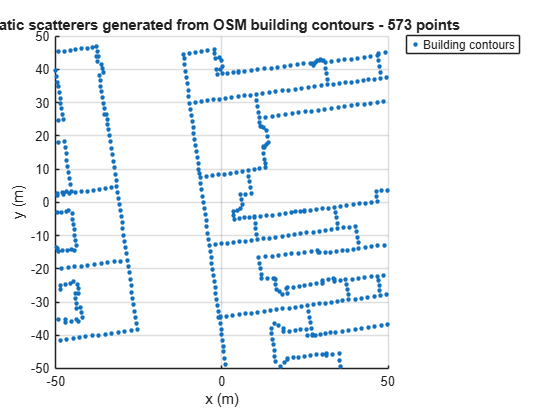

Generated 573 static scatterers inside ROI.
Scatterer spacing: 2.00 m


%% OSM STEP 5 - Generate static scatterers from building contours inside ROI

scattererSpacing = 2; % meters

[scattererPositions, reflectionCoefficients] = ...
    helperGenerateOSMBuildingScatterersFromROI(osmLocal, scenarioROI, scattererSpacing);

%% OSM STEP 6 - Save generated static scatterers

switch scenarioName

    case "openArea"
        scattererMatFile = "open_area_osm_scatterers.mat";

    case "piotrkowskaStreetCanyon"
        scattererMatFile = "piotrkowska_osm_scatterers.mat";

    otherwise
        error("Unknown scenarioName: %s", scenarioName);

end

save(scattererMatFile, ...
    "scattererPositions", ...
    "reflectionCoefficients", ...
    "scenarioROI", ...
    "scattererSpacing");

fprintf("Saved OSM static scatterers to: %s\n", scattererMatFile);

Saved OSM static scatterers to: piotrkowska_osm_scatterers.mat
